# IFDIFF - A Matlab Toolkit for ODEs with State˗Dependent Switches

The software package `IFDIFF` deals with the solution and algorithmic generation of sensitivities in ordinary differential equations with implicit (state-dependent) non-differentiabilites (“switches”) in the right-hand side that is given as Matlab program code with non-differentiable operators such as `min`, `max`, `abs`, `sign`, as well as `if`-branching. `IFDIFF` automatically generates only necessary switching functions, outputs them as Matlab code, and detects switching points accurately up to machine precision.

`IFDIFF` handles multidimensional state and parameter vectors and can be transparently used in existing code, as it generates `sol` solution structures compatible to the `MATLAB` ode solvers. No modifications to the right hand side or manual processing are necessary. A single preparation call is sufficient.

In the `PErFDiff` project, the existing implementation is to be further developed and extended for Filippov systems.

For a more in-depth explanation of the package please visit [`IFDIFF`](https://andreassommer.github.io/ifdiff/).

## A first example and demonstration of the `IFDIFF` library

The first thing to do when solving switched ODEs with `IFDIFF` is to define the Initial value problem (IVP). Lets take a look at the following canonical example ODE:


$$\dot{x} = f(t,x,p) = \pmatrix{f_1(t,x,p) \cr f_2(t,x,p)} \\ \\

f_1(t,x,p) = 0.01 \cdot t^2 + x_2^3 \hspace{20pt} f_2(t,x,p) = \begin{cases} 
0 & \text{if} & x_1 < p \\ 5 & \text{if} & p \leq x_1 < p +0.5 \\ 0 & \text{if} & x_1 \geq p + 0.5 \end{cases}$$


With the initial value:

$x(0) = (1,0)^T \hspace{20pt} \text{and the paramteter} \hspace{20pt} p=5.437$.

The **Right-Hand-Side** (RHS) is stored in a separate `MATLAB` function file called `canonicalExampleRHS.m`. It can be found [here](matlab:open('./canonicalExampleRHS.m')). and looks like:

### Initialization:

The initial values, the time interval, the parameter(s) as well as the integrator (here Runge Kuta 45) can be defined as follows:

clear;
initPaths();

integrator = @ode45;
t0 = 0;
tf = 20;
timeinterval = [t0,tf];
initstates   = [1  0 ];
p            = 5.437;

fprintf('Preprocessing...\n  ');

Preprocessing...
  

### Integration-Options and Datahandle:

Next, we define the integrator options, refer the file name of the RHS and prepare the **Datahandle **using the function `prepareDatahandleForIntegration()`.

odeoptions = odeset( 'AbsTol', 1e-20, 'RelTol', 1e-12);
filename = 'canonicalExampleRHS';
th = tic();
dhandle = prepareDatahandleForIntegration(filename, 'integrator', func2str(integrator), 'options', odeoptions);
time_prepare = toc(th); fprintf('Took %g seconds\n', time_prepare);

Took 5.87992 seconds


### Integration:

Now, we can solve our first ODE with `IFDIFF`. The `solveODE()` function takes care of this and is called with the datahalnde as well as all previously defined parameters and states of the IVP.

fprintf('Integration with ifdiff/%s...\n  ', func2str(integrator));

Integration with ifdiff/ode45...
  

th = tic();
sol_ifdiff = solveODE(dhandle, timeinterval, initstates, p);
time_ifdiff = toc(th); fprintf('Took %g seconds\n', time_ifdiff);

Took 1.13137 seconds


### Naive Integration:

For demonstration purposes we want to compare this result to the naive approach when using `MATLAB` integration.

fprintf('Integration with %s...\n  ', func2str(integrator));

Integration with ode45...
  

th = tic();
sol_matlab = integrator(@(t,x) canonicalExampleRHS(t,x,p), timeinterval, initstates, odeoptions);
time_matlab = toc(th); fprintf('Took %g seconds\n', time_matlab);

Took 0.0410731 seconds


### Accurate Euler Integration:

As it is common practice, we check the results against an Euler integration with small stepsize.

th = tic();
N_euler =3000000;
X = zeros(2, N_euler+1); % solution array
X(:,1) = initstates;     % copy initial state
T = zeros(1, N_euler+1); % time array
T(1) = t0;               % copy initial time point
dt = (tf-t0) / N_euler;  % time increment
for k = 1:N_euler
   T(k+1)   = t0 + k*dt;
   X(:,k+1) = X(:,k) + dt * canonicalExampleRHS(T(k), X(:,k), p);
end
time_euler = toc(th); fprintf('Took %g seconds\n', time_euler);
skipper = floor(N_euler/1000);

Took 1.46266 seconds


T_euler = T(1:skipper:end);
Y_euler = X(:,1:skipper:end);
T = T_euler;
Y_matlabsolver = deval(sol_matlab, T);
Y_ifdiff       = deval(sol_ifdiff, T);

Note that the `sol` structure returned by `solveODE` is an augmented version of the solution structures returned by Matlab’s very own integrators (see [Matlab documentation](https://de.mathworks.com/help/matlab/ref/deval.html#bu7iw_j-sol)), and can thus be evaluated using `deval`. That means, `IFDIFF` can be used transparently within existing code!

## Solutions

### Plot the Solution-Trajectories of all Integrators:

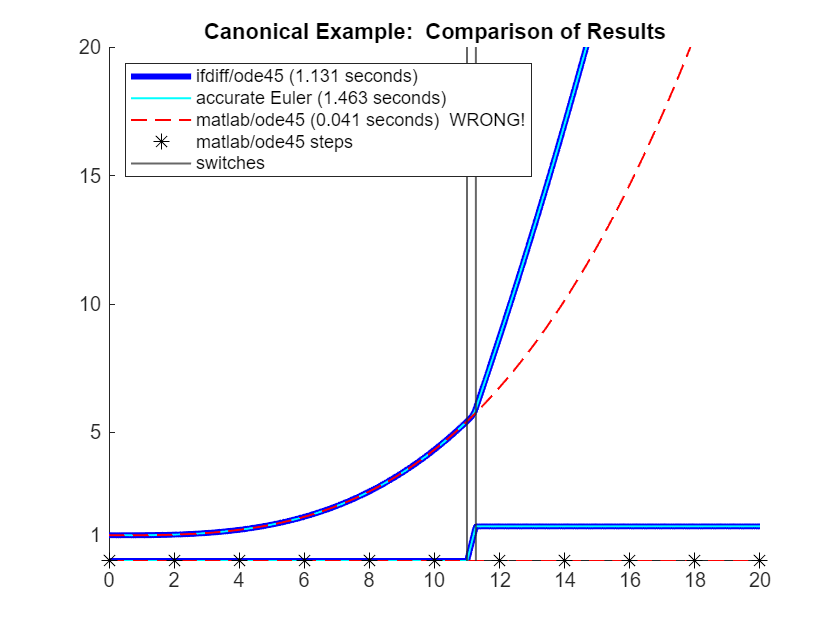

fignum = 544; figure(fignum); clf('reset'); hold('on');
ymax = 20; % set to multiple of 5
axis([0 tf 0 ymax])
plot(T, Y_ifdiff      , 'b-' , 'lineWidth', 3);
plot(T, Y_euler       , 'c-' , 'LineWidth', 1);
plot(T, Y_matlabsolver, 'r--', 'lineWidth', 1);
plot(sol_matlab.x, zeros(size(sol_matlab.x)), 'k*', 'MarkerSize', 8);   % step sizes by matlab integrator
xline(sol_ifdiff.switches(1), '-', 'lineWidth', 1.0);
xline(sol_ifdiff.switches(2), '-', 'lineWidth', 1.0);
set(gca,'XTick',0:2:tf); 
set(gca,'YTick',[1 5:5:ymax]); 
title('Canonical Example:  Comparison of Results');
legend(sprintf('ifdiff/%s (%5.3f seconds)'        , func2str(integrator), time_ifdiff), '', ...
       sprintf('accurate Euler (%5.3f seconds)'                         , time_euler) , '', ...
       sprintf('matlab/%s (%5.3f seconds)  WRONG!', func2str(integrator), time_matlab), '', ...
       sprintf('matlab/%s steps'                  , func2str(integrator))                 , ...
       'switches', '', ...
       'Location', 'NorthWest');

### Plot the Difference-Trajectories of the the Integrators compared to `IFDIFF`

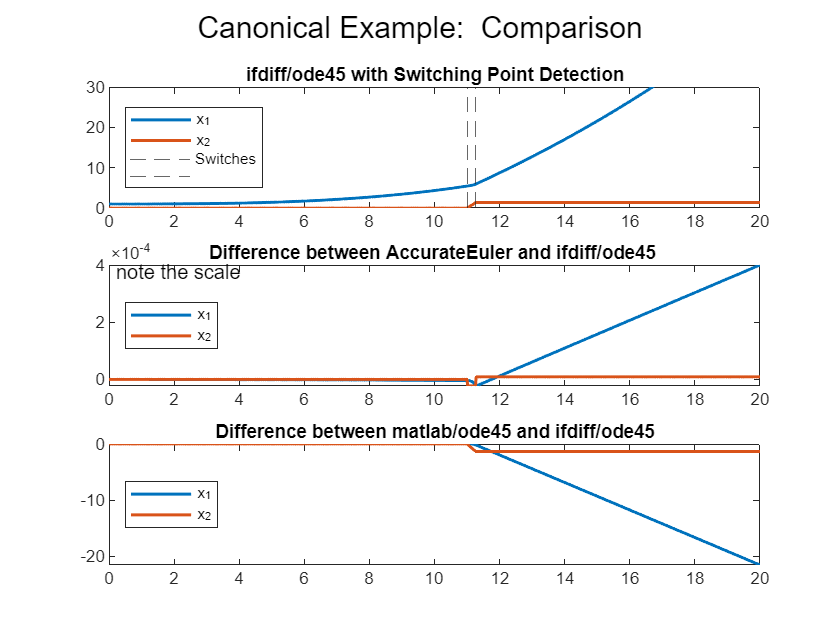

Ydiff_Euler  = Y_euler        - Y_ifdiff;
Ydiff_Matlab = Y_matlabsolver - Y_ifdiff;

% plot prepare
fignum = fignum + 1; figure(fignum); clf;
ymax = 30;
axes = [0 tf 0 ymax]; 
lw = 1.5;

% plot ifdiff
ax2 = subplot(3,1,1); plot(T, Y_ifdiff, 'linewidth', lw); 
legend('x_1','x_2','Location','West'); 
title(sprintf('ifdiff/%s with Switching Point Detection', func2str(integrator))); 
axis(axes); 
% plot switches
xline(sol_ifdiff.switches(1), '--', 'DisplayName', 'Switches'); 
xline(sol_ifdiff.switches(2), '--', 'DisplayName', '');

ax3 = subplot(3,1,2); plot(T, Ydiff_Euler ,'linewidth', lw); 
legend('x_1','x_2','Location','West'); 
title(sprintf('Difference between AccurateEuler and ifdiff/%s ', func2str(integrator)));
text(t0+0.2, max(Ydiff_Euler(:))*0.94, 'note the scale')

ax4 = subplot(3,1,3); plot(T, Ydiff_Matlab,'linewidth', lw);
legend('x_1','x_2','Location','West');
title(sprintf('Difference between matlab/%1$s and ifdiff/%1$s', func2str(integrator)));

sgtitle('Canonical Example:  Comparison');
linkaxes([ax2 ax3 ax4], 'x');